clear
clc

loadSim

Loading file: D06_05_h05_Ea_An00H00_R01
Loading file: D06_05_h05_Eb_An00H00_R01
Loading file: D06_05_h05_Ed_As10H05_R01
Loading file: D06_05_h05_Ef_Ab05H02_R01
Loading file: D06_05_h05_Ef_Ab05H05_R01
Loading file: D06_05_h05_Ef_Ac05H0108_R01
Loading file: D06_05_h05_Ef_Ac08H0108_R01
Loading file: D06_05_h05_Ef_As03H02_R01
Loading file: D06_05_h05_Ef_As03H05_R01
Loading file: D06_05_h05_Ef_As03H10_R01
Loading file: D06_05_h05_Ef_As05H05_R01
Loading file: D06_05_h05_Ef_As07H02_R01
Loading file: D06_05_h05_Ef_As10H05_R01
Elapsed time is 0.084919 seconds.
Data loaded


y = D06_05_h05_Ef_Ab05H02_R01.data(:,2:3);
u = D06_05_h05_Ef_Ab05H02_R01.data(:,5);
z1 = iddata(y, u, 0.05, 'Name', 'Pendulum');
z1.OutputName = {'Pendulum position','Flywheel angular velocity'};
z1.OutputUnit = {'rad','rad/s'};
z1.InputName = {'Control Signal'};
z1.Tstart = 0;
z1.TimeUnit = 's';

y = D06_05_h05_Ef_As05H05_R01.data(:,2:3);
u = D06_05_h05_Ef_As05H05_R01.data(:,5);
z2 = iddata(y, u, 0.05, 'Name', 'Pendulum');
z2.OutputName = {'Pendulum position','Flywheel angular velocity'};
z2.OutputUnit = {'rad','rad/s'};
z2.InputName = {'Control Signal'};
z2.Tstart = 0;
z2.TimeUnit = 's';

FileName      = 'flywheel_extended';        % File describing the model structure.
Order         = [2 1 3];             % Model orders [ny nu nx].
Parameters    = [9.81; 0.209; 0.18; 0.492; 0.05; 2.3e-4; 0.029; 0.027; 0.025; 0.5; 1.32e-6];   % Initial parameters. %g,Mf,lf,mp,lp,Jf,Jm,c_u,c_v,R,mu_m
InitialStates = [0; 0; 0];              % Initial initial states.
Ts            = 0;                   % Time-continuous system.
nlgr = idnlgrey(FileName, Order, Parameters, InitialStates, Ts);
nlgr.OutputName = {'Pendulum position','Flywheel angular velocity'};
nlgr.OutputUnit = {'rad','rad/s'};
nlgr.TimeUnit = 's';
nlgr = setinit(nlgr, 'Name', {'Pendulum position' 'Pendulum velocity' 'Flywheel velocity'});
nlgr = setinit(nlgr, 'Unit', {'rad' 'rad/s' 'rad/s'});
nlgr = setpar(nlgr, 'Name', {'Gravity constant' 'Flywheel mass' 'flywheel length' 'pendulum mass' 'pendulum cog length' 'flywheel inertia' ...
    'pendulum inertia' 'motor torque constant' 'back emf constant' 'motor resistance' 'dynamic friction torque'});
nlgr = setpar(nlgr, 'Unit', {'m/s^2' 'kg' 'm' 'kg' 'm' 'inertia' 'inertia' 'idk' 'idk' 'idk' 'idk'});
nlgr = setpar(nlgr, 'Minimum', {eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0) eps(0)});   % All parameters > 0.
nlgr = setpar(nlgr, 'Maximum', {20 2 0.3 3 0.2 inf inf 2 1 inf 1e-4});   % All parameters > 0.


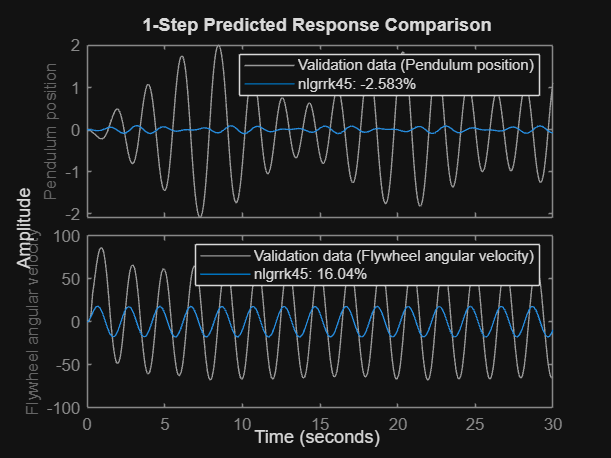

nlgrrk45 = nlgr;
nlgrrk45.SimulationOptions.Solver = 'ode45';     % Runge-Kutta 45.

compare(z2, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

nlgrrk45 = setpar(nlgrrk45, 'Fixed', {true false false false false false false false false false false});

We finally use the Runge-Kutta 45 solver (ode45).

opt = nlgreyestOptions('Display', 'on');
opt.OutputWeight = [1000,0;0,1];
nlgrrk45 = nlgreyest(z2, nlgrrk45, opt)   % Perform parameter estimation.

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-0.7898;22.53]%                                        
FPE: 1081, MSE: 1327                                                            

Model Properties


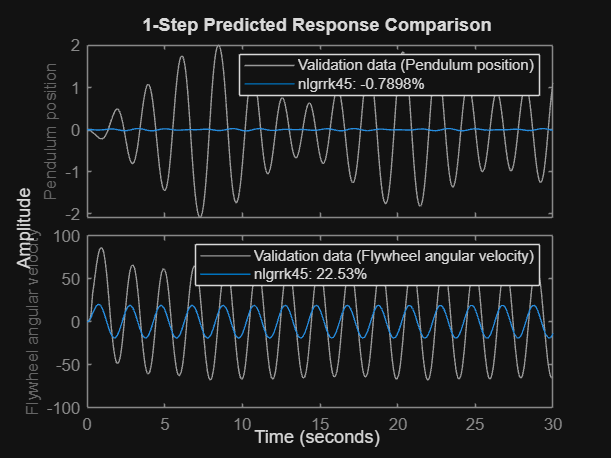

compare(z2, nlgrrk45, 1, ...
   compareOptions('InitialCondition', 'model'));

fpe(nlgrrk45);

   1.0808e+03



nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-0.4483;94.43]%                                        
FPE: 3.19, MSE: 45.64                                                           

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-0.05617;94.94]%                                       
FPE: 5.24, MSE: 6.553                                                           

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-0.05593;94.94]%                                       
FPE: 5.241, MSE: 6.553                                                          

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-0.3863;94.6]%                                         
FPE: 2.156, MSE: 42.93                                                          

Model Properties


ans = 11×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


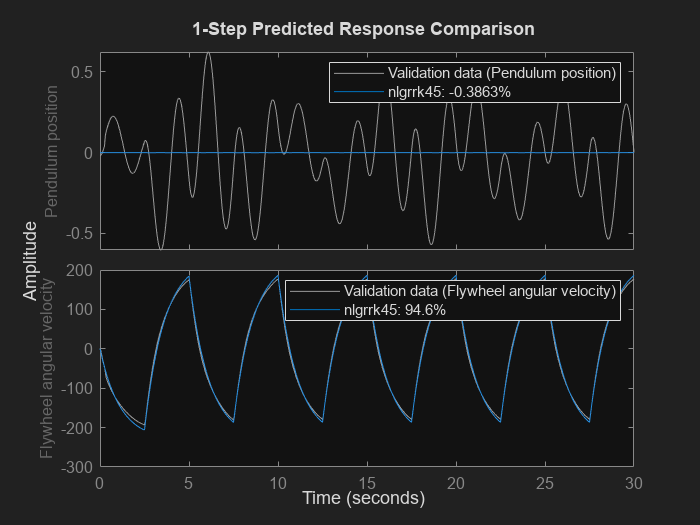

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-0.3263;97.37]%                                        
FPE: 0.5859, MSE: 10.23                                                         

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-0.04969;94.83]%                                       
FPE: 5.396, MSE: 6.804                                                          

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-0.04849;95]%                                          
FPE: 5.151, MSE: 6.43                                                           

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [17.41;97.43]%                                          
FPE: 0.4073, MSE: 9.723                                                         

Model Properties


ans = 11×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


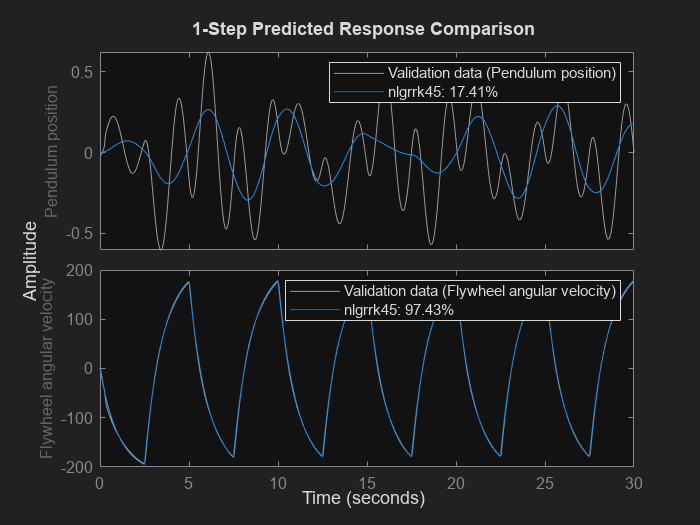

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [17.41;97.43]%                                          
FPE: 0.4075, MSE: 9.726                                                         

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [10.99;77.83]%                                          
FPE: 64.24, MSE: 109.3                                                          

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [10.99;77.83]%                                          
FPE: 64.24, MSE: 109.3                                                          

Model Properties


nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-3003;78.31]%                                          
FPE: 4.874e+04, MSE: 759.2                                                      

Model Properties


ans = 11×1 struct array with fields:
    Name
    Unit
    Value
    Minimum
    Maximum
    Fixed


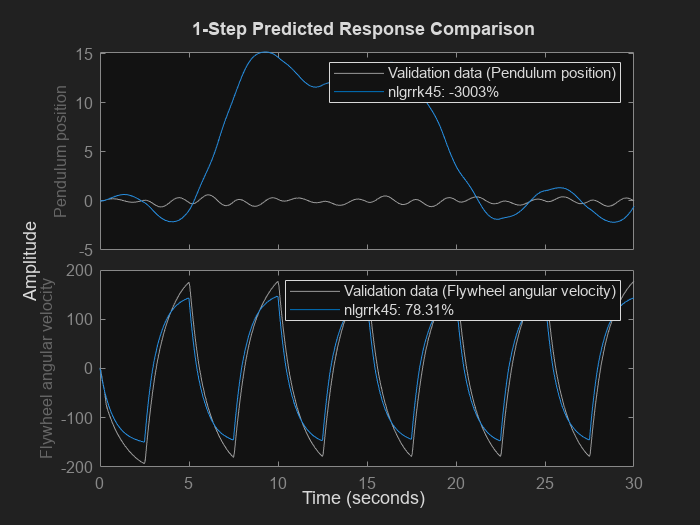

nlgrrk45 =

Continuous-time nonlinear grey-box model defined by 'flywheel_extended' (MATLAB file):

   dx/dt = F(t, u(t), x(t), p1, ..., p11)
    y(t) = H(t, u(t), x(t), p1, ..., p11) + e(t)

 with 1 input(s), 3 state(s), 2 output(s), and 10 free parameter(s) (out of 11).

Status:                                                                         
Estimated using Solver: ode45; Search: lsqnonlin on time domain data "Pendulum".
Fit to estimation data: [-3003;78.31]%                                          
FPE: 4.874e+04, MSE: 759.2                                                      

Model Properties





for i = 1:4 
    opt.OutputWeight = [1000000,0;0,1];
    nlgrrk45 = nlgreyest(z1,nlgrrk45, opt)
    nlgrrk45 = pem(z2,nlgrrk45, opt)
    nlgrrk45 = nlgreyest(z2,nlgrrk45, opt)
    nlgrrk45 = pem(z1,nlgrrk45, opt)
    
    nlgrrk45.Parameters
    figure(i),clf;
        compare(z1, nlgrrk45, 1, ...
        compareOptions('InitialCondition', 'model'));
end